clc                     % clear command window
clear                   % clear MATLAB workspace
clf

[robotArduino]= SETUPARDUINO('COM3') 

robotArduino =   arduino with properties:

                  Port: 'COM3'
                 Board: 'Nano33BLE'
         AvailablePins: {'D0-D13', 'A0-A7'}
  AvailableDigitalPins: {'D0-D13', 'A0-A7'}
      AvailablePWMPins: {'D0-D13'}
   AvailableAnalogPins: {'A0-A3', 'A6-A7'}
    AvailableI2CBusIDs: [0, 1]
AvailableSerialPortIDs: [1]
             Libraries: {'I2C', 'Servo'}
Show all properties


steerServo = servo(robotArduino, 'D5', 'MinPulseDuration', 1466*10^-6, ...
      'MaxPulseDuration', 1536*10^-6);

Pin D5 is reserved by other servo object(s) in the current workspace. Clear all variables holding onto this resource
first.

driveServo = servo(robotArduino, 'D3', 'MinPulseDuration', 1466*10^-6, ...
      'MaxPulseDuration', 1536*10^-6);
panServo = servo(robotArduino, 'D6', 'MinPulseDuration', 1466*10^-6, ...
      'MaxPulseDuration', 1536*10^-6);

writePosition(steerServo, 0.5);      % always start servo-command at 0.5
writePosition(driveServo, 0.3);      % always start servo-command at 0.5
writePosition(panServo, 0.5);        % always start servo-command at 0.5
pause(3.0);                          % wait for Arduino to send stable pwm
warning ('actuators live');

% calibrate to 0.1 - 0.3 - 0.9
writePosition(driveServo, 0.3);  % 0.359 to 0.37 for speeds
writePosition(steerServo, 0.51);
writePosition(panServo, 0.43);

joy=vrjoystick(1); 
while true
    one = axis(joy, 1)
    two = axis(joy, 2)
    three = axis(joy, 3)
    writePosition(steerServo, -one*0.16 + 0.54)
    writePosition(driveServo, -two*0.02 + 0.35)
    writePosition(panServo, -three*0.5 + 0.5)
    
    pause(0.01)


end

clear lid
lid = LIDAR('COM6')

lid =   LIDAR with properties:

        lidar: [1×1 serial]
     pol_data: []
    cart_data: []


lidar_data = lid.scan(5000);

   5.0952e+03



slope = 23.2678

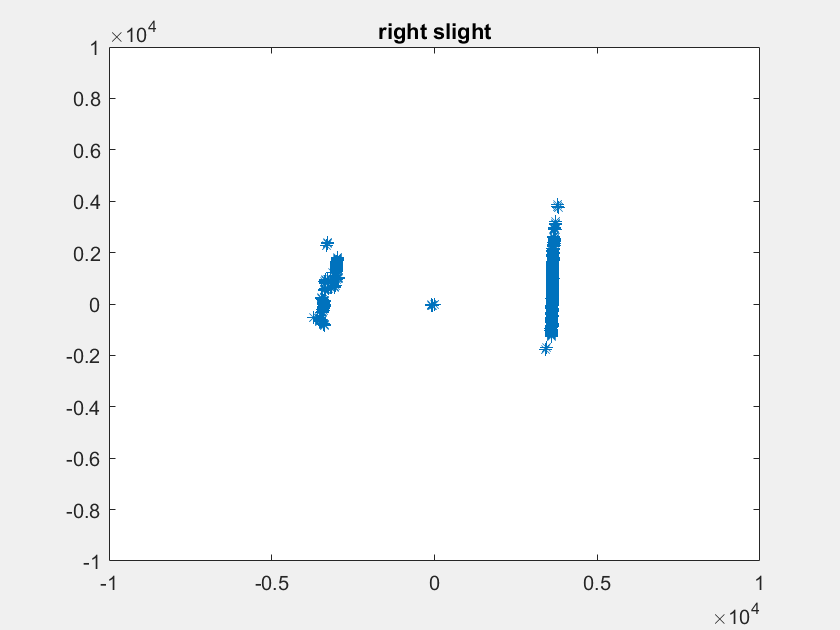

   5.0267e+03



slope = 1.3984

   4.3986e+03



slope = -2.6590

   4.1400e+03



slope = -3.1871

   3.7553e+03



slope = -2.5452

   3.5207e+03



slope = -2.1477

   3.2917e+03



slope = -2.5201

   3.1979e+03



slope = 0.0148

   3.0308e+03



slope = 1.1269

   2.8833e+03



slope = 0.2876

   2.9564e+03



slope = -3.3357

   3.3429e+03



slope = 12.0152

   3.4783e+03



slope = 4.3444

   3.3496e+03



slope = -0.4919

   3.2108e+03



slope = -3.7524

   3.1300e+03



slope = -4.6857

   3.1075e+03



slope = -5.3442

   3.0849e+03



slope = -4.3903

   3.0859e+03



slope = -4.7302

   2.8850e+03



slope = -1.5348

   2.8312e+03



slope = 3.4869

   2.9568e+03



slope = 2.3869

   3.0798e+03



slope = 2.2446

   3.3083e+03



slope = 1.5639

   3.5530e+03



slope = 2.1672

   3.7318e+03



slope = 3.0030

   4.1049e+03



slope = 3.9936

   3.8625e+03



slope = 3.4599

   4.0136e+03



slope = 4.4620

   3.8324e+03



slope = 3.6060

   4.1512e+03



slope = 0.0020

   4.0500e+03



slope = -4.7472

   3.8301e+03



slope = 0.3597

   3.7229e+03



slope = -1.4237

  999.8203



slope = 0.5310

  854.9036



slope = 0.7489

  994.4663



slope = 0.8796

   3.6514e+03



slope = 3.5737

   4.2954e+03



slope = 0.4613

   5.1103e+03



slope = 1.2374

  778.6932



slope = -0.0758

  688.0848



slope = -0.3744

  573.0639



slope = 0.6559

slope = 0

rights =        20000
       20000


  556.9307



slope = -0.2081

slope = 0

rights =        20000
       20000


slope = 0

rights =        20000
       20000


slope = 0

rights =        20000
       20000


slope = 0

rights =        20000
       20000


slope = 0

rights =        20000
       20000


slope = 0

rights =        20000
       20000


slope = 0

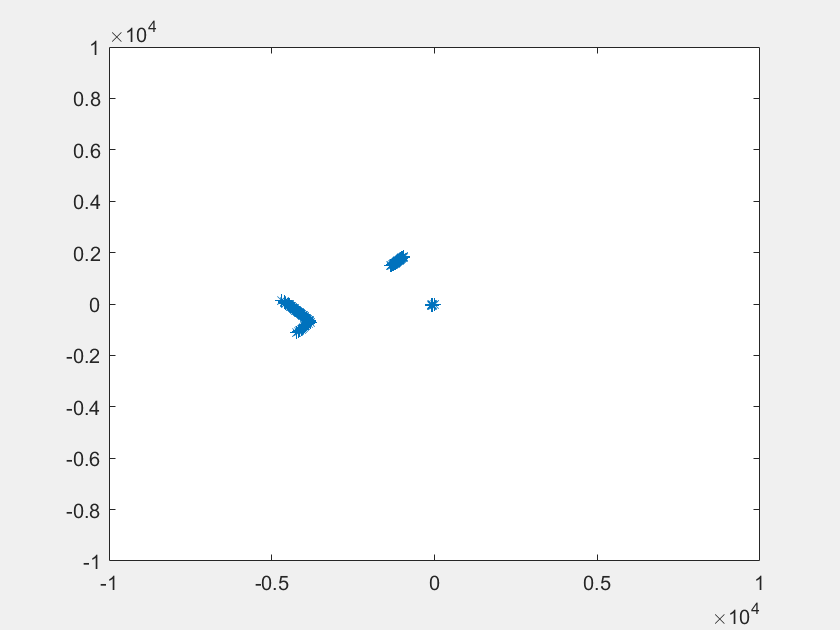

Invalid position value. The value must be between 0 and 1.

lid.close()

cam = Camera();

obj =   Camera with properties:

           cam: [1×1 webcam]
    intrinsics: [1×1 cameraIntrinsics]
       tagSize: []


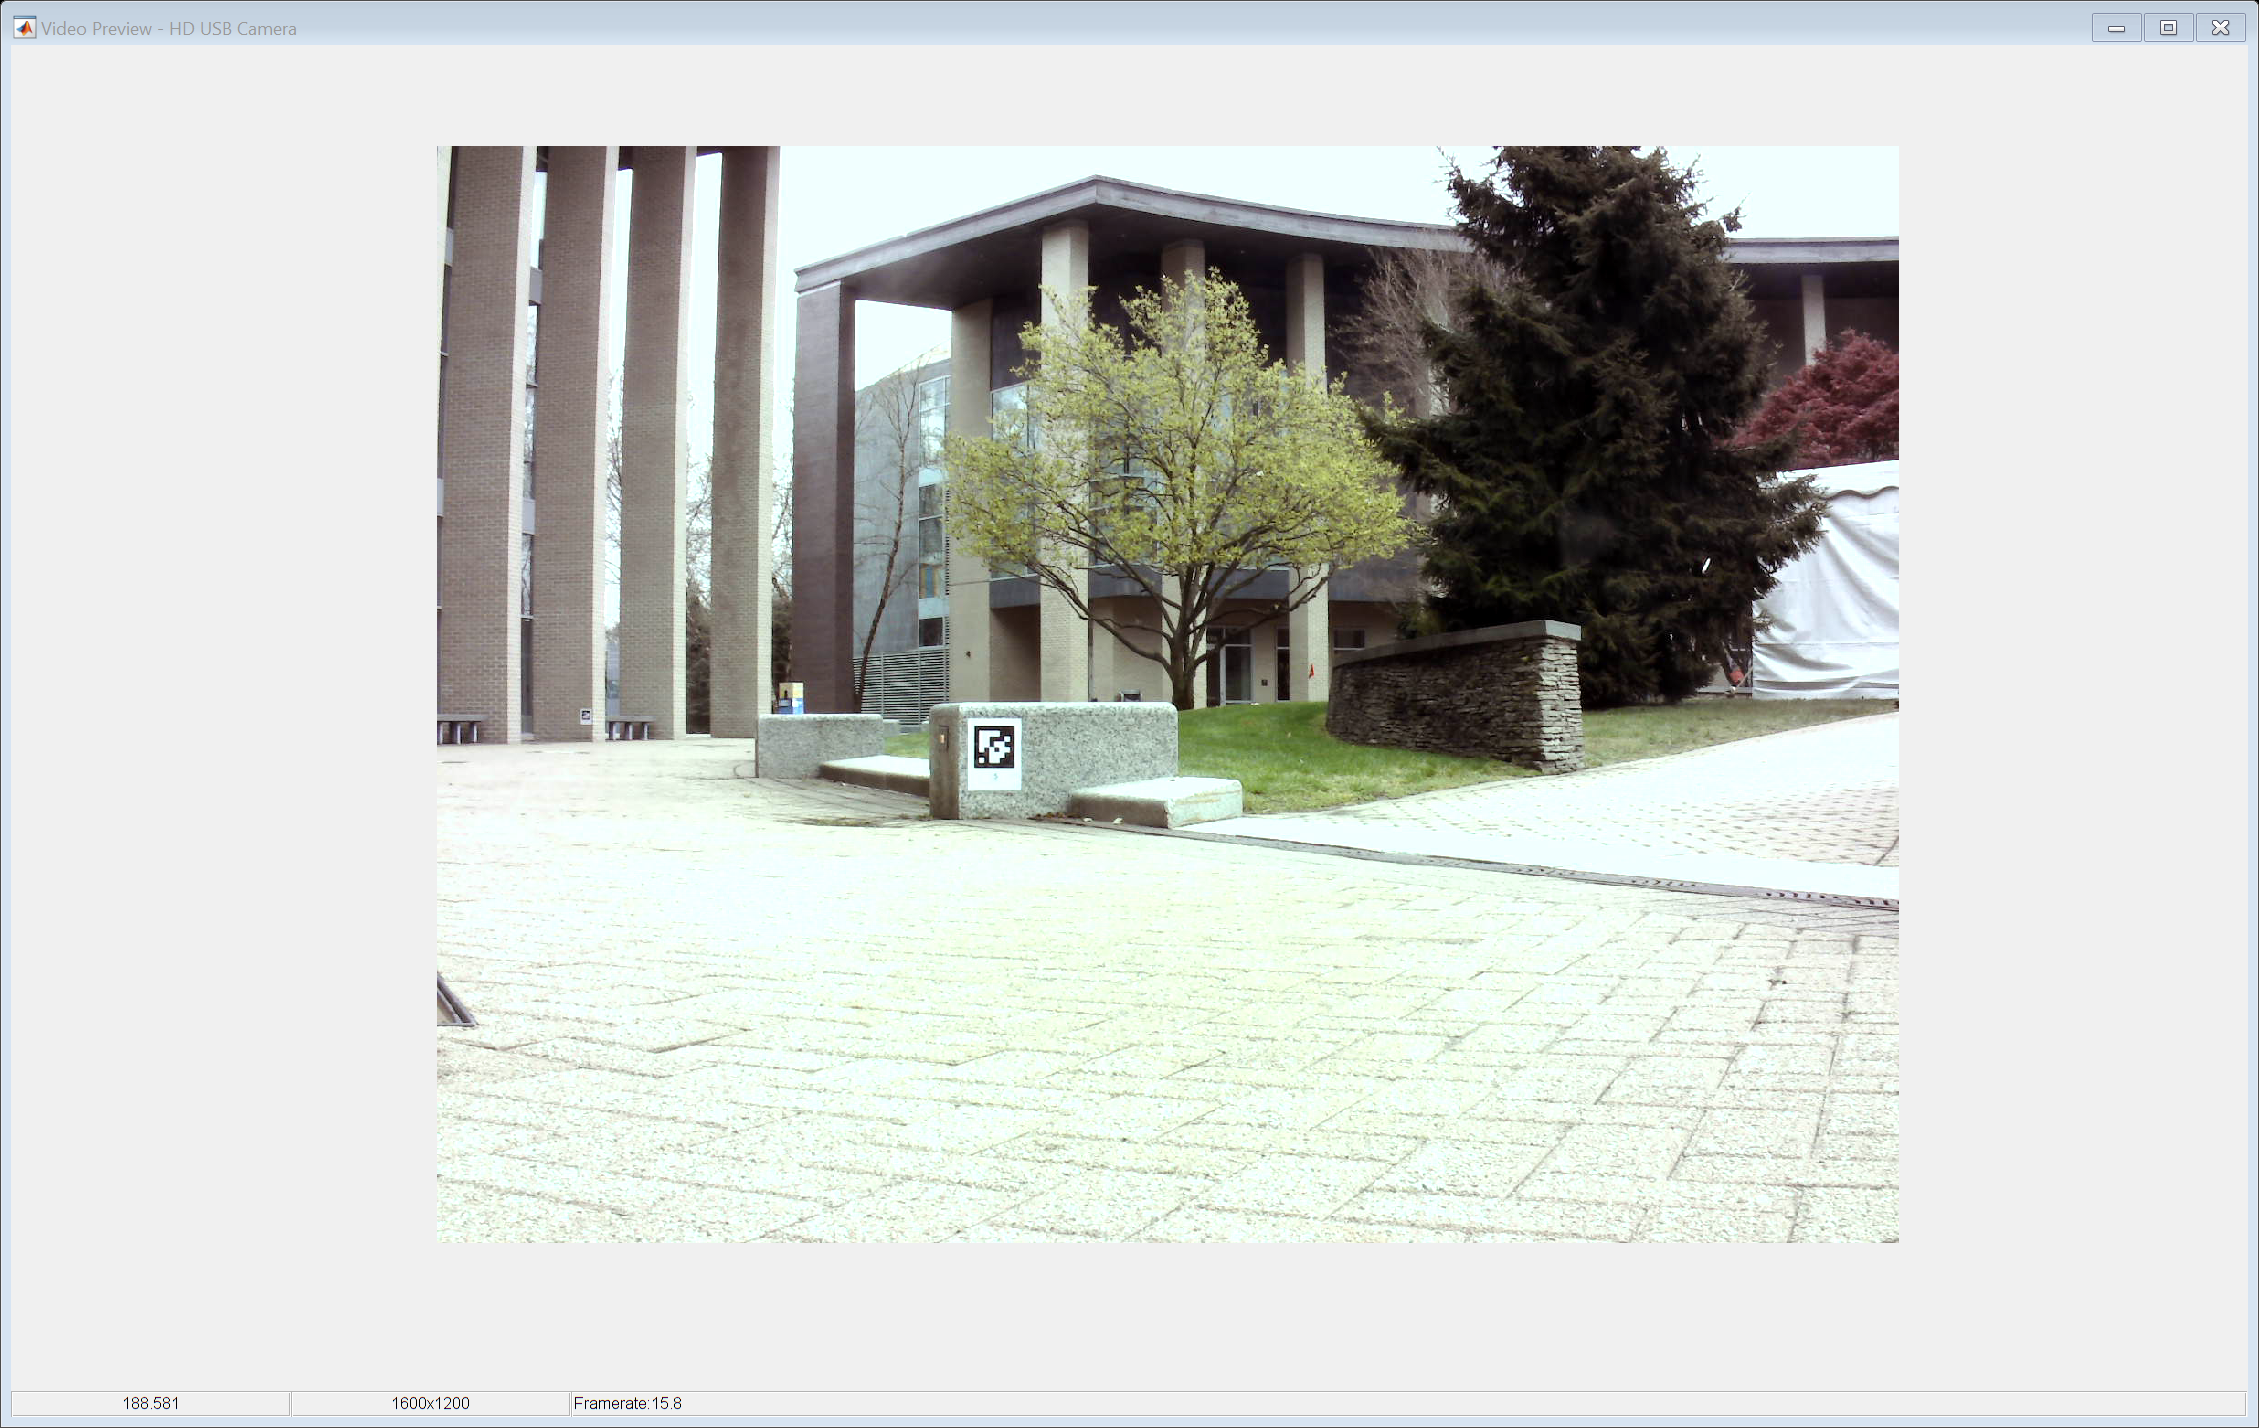

cam.show

RANSAC fit

% calibrate to 0.1 - 0.3 - 0.9
writePosition(driveServo, 0.3);  % 0.359 to 0.37 for speeds
writePosition(steerServo, 0.51);
writePosition(panServo, 0.43);

outer = [1 2 3 5 7 8 9 10 11 12];
inner = [4 6 13 14 15 16];
target = [0];

while true

    turn = 0
    
    [id,loc,pose] = cam.poses();
    for i = 1:length(pose)
        tagnum = id(i);
        x = pose(i).Translation(1);
        y = pose(i).Translation(3);
        r = pose(i).Rotation(1);
        if y < 8
            break
        end
    end

    if ismember(outer, tagnum)
        if x < -3
            turn = -2;
        elseif x > -0.5
            turn = 2;
        end
    elseif ismember(inner, tagnum)
        if x < 0.5
            turn = -2;
        elseif x > 3
            turn = 2;
        end
    elseif ismember(target, tagnum)
        break
    end

    if turn == 2
        writePosition(steerServo, 0.3*0.16 + 0.52);
    elseif turn == -2
        writePosition(steerServo, -0.3*0.16 + 0.52);
    else
        writePosition(steerServo, 0.52);
    end
    turn

    pause(0.1)
end

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

turn = 0

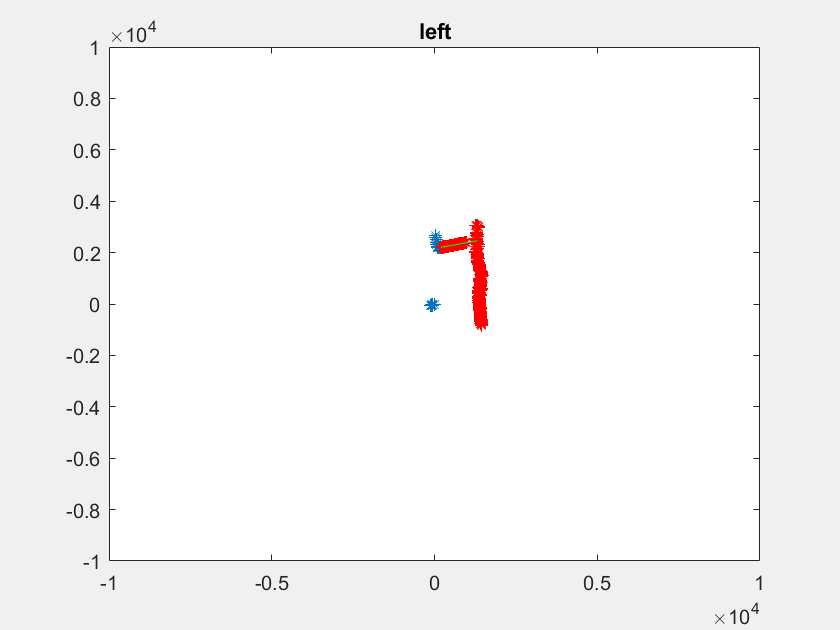

   1.9172e+03



rpoints = 	1.0e+03 *

    1.4480   -0.8360
    1.4453   -0.8226
    1.4459   -0.8113
    1.4334   -0.7927
    1.4321   -0.7806
    1.4369   -0.7717
    1.4416   -0.7629
    1.4285   -0.7448
    1.4295   -0.7342
    1.4340   -0.7254


slope = 0.2289

   1.5234e+03



rpoints = 	1.0e+03 *

    1.5666   -0.9045
    1.5730   -0.8954
    1.5785   -0.8857
    1.5830   -0.8755
    1.5884   -0.8657
    1.5937   -0.8560
    1.5865   -0.8396
    1.5917   -0.8299
    1.5967   -0.8201
    1.6053   -0.8120


slope = 1.9981

   1.6240e+03



rpoints = 	1.0e+03 *

    1.6680   -0.9630
    1.6738   -0.9527
    1.6797   -0.9424
    1.6854   -0.9321
    1.6911   -0.9217
    1.7029   -0.9146
    1.7085   -0.9042
    1.7096   -0.8913
    1.7150   -0.8808
    1.7204   -0.8703


slope = 1.4563

   1.6887e+03



rpoints = 	1.0e+03 *

    1.7182   -0.9920
    1.7164   -0.9770
    1.7224   -0.9664
    1.7283   -0.9558
    1.7324   -0.9442
    1.7232   -0.9255
    1.4743   -0.7802
    1.3318   -0.6944
    1.2133   -0.6232
    1.1243   -0.5688


slope = 1.3315

   1.7555e+03



rpoints = 	1.0e+03 *

    1.1527   -0.6655
    1.1515   -0.6554
    1.1564   -0.6488
    1.1604   -0.6417
    1.1643   -0.6346
    1.1682   -0.6274
    1.1720   -0.6202
    1.1758   -0.6130
    1.1769   -0.6044
    1.1805   -0.5972


slope = 1.4752

   1.8507e+03



rpoints = 	1.0e+03 *

    1.2116   -0.6995
    1.2158   -0.6920
    1.2253   -0.6875
    1.2295   -0.6800
    1.2337   -0.6724
    1.2378   -0.6648
    1.2348   -0.6535
    1.2387   -0.6459
    1.2454   -0.6396
    1.2493   -0.6319


slope = 1.2851

   1.9579e+03



rpoints = 	1.0e+03 *

    1.2817   -0.7400
    1.2862   -0.7321
    1.2872   -0.7222
    1.2916   -0.7143
    1.2960   -0.7064
    1.3056   -0.7012
    1.3116   -0.6941
    1.3159   -0.6861
    1.3219   -0.6789
    1.3269   -0.6712


slope = 1.2820

   2.0663e+03



rpoints = 	1.0e+03 *

    1.3527   -0.7810
    1.3584   -0.7732
    1.3701   -0.7687
    1.3748   -0.7603
    1.3838   -0.7542
    1.9108   -1.0263
    1.9286   -1.0206
    1.9357   -1.0092
    1.9481   -1.0005
    1.9542   -0.9885


slope = 1.2541

   3.1360e+03



rpoints = 	1.0e+03 *

    2.0551   -1.1865
    2.0571   -1.1709
    2.0695   -1.1612
    2.0801   -1.1504
    2.0845   -1.1361
    2.0941   -1.1247
    2.1009   -1.1118
    2.1077   -1.0989
    2.1322   -1.0951
    2.1389   -1.0820


slope = 1.0876

   3.1127e+03



rpoints = 	1.0e+03 *

    2.0378   -1.1765
    2.0467   -1.1650
    2.0643   -1.1582
    2.0713   -1.1455
    2.0783   -1.1328
    2.0853   -1.1200
    2.0983   -1.1104
    2.1219   -1.1063
    2.1331   -1.0956
    2.1425   -1.0838


slope = 0.9889

   3.2027e+03



rpoints = 	1.0e+03 *

    2.0966   -1.2105
    2.1075   -1.1996
    2.1175   -1.1881
    2.1308   -1.1784
    2.1468   -1.1701
    2.1522   -1.1560
    2.1610   -1.1437
    2.1725   -1.1327
    2.1829   -1.1211
    2.2058   -1.1158


slope = 0.9670

   3.1683e+03



rpoints = 	1.0e+03 *

    2.0741   -1.1975
    2.0814   -1.1847
    2.0896   -1.1724
    2.0993   -1.1610
    2.1126   -1.1515
    2.1196   -1.1385
    2.1266   -1.1254
    2.1361   -1.1137
    2.1571   -1.1079
    2.1621   -1.0937


slope = 1.0296

   3.1802e+03



rpoints = 	1.0e+03 *

    2.0819   -1.2020
    2.0927   -1.1912
    2.1026   -1.1798
    2.1125   -1.1683
    2.1214   -1.1562
    2.1293   -1.1437
    2.1389   -1.1320
    2.1459   -1.1188
    2.1580   -1.1083
    2.1701   -1.0978


slope = 1.0255

   3.4262e+03



rpoints = 	1.0e+03 *

    2.2430   -1.2950
    2.2509   -1.2812
    2.2727   -1.2752
    2.2805   -1.2612
    2.2882   -1.2472
    2.2870   -1.2284
    2.2945   -1.2143
    2.3019   -1.2002
    2.3092   -1.1860
    2.3334   -1.1804


slope = 1.2259

   3.5175e+03



rpoints = 	1.0e+03 *

    2.3028   -1.3295
    2.3109   -1.3153
    2.3180   -1.3006
    2.3234   -1.2849
    2.3268   -1.2682
    2.3346   -1.2539
    2.3422   -1.2395
    2.3498   -1.2251
    2.3644   -1.2143
    2.3754   -1.2016


slope = 1.2644

   3.5850e+03



rpoints = 	1.0e+03 *

    2.3469   -1.3550
    2.3561   -1.3411
    2.3739   -1.3319
    2.3811   -1.3169
    2.3892   -1.3022
    2.3989   -1.2885
    2.4067   -1.2737
    2.4225   -1.2630
    2.4311   -1.2486
    2.4512   -1.2400


slope = 1.2499

   3.4805e+03



rpoints = 	1.0e+03 *

    2.2785   -1.3155
    2.2865   -1.3015
    2.2945   -1.2874
    2.3024   -1.2733
    2.3101   -1.2591
    2.3169   -1.2444
    2.3422   -1.2395
    2.3569   -1.2288
    2.3644   -1.2143
    2.3736   -1.2007


slope = 1.1788

   3.4924e+03



rpoints = 	1.0e+03 *

    2.2863   -1.3200
    2.2970   -1.3074
    2.3085   -1.2952
    2.3207   -1.2835
    2.3312   -1.2706
    2.3390   -1.2563
    2.3484   -1.2428
    2.3569   -1.2288
    2.3671   -1.2157
    2.3798   -1.2039


slope = 1.1781

   3.5546e+03



rpoints = 	1.0e+03 *

    2.3270   -1.3435
    2.3352   -1.3292
    2.3468   -1.3168
    2.3549   -1.3023
    2.3672   -1.2902
    2.3804   -1.2785
    2.3891   -1.2643
    2.3968   -1.2496
    2.4053   -1.2354
    2.4209   -1.2246


slope = 1.2055

   3.6207e+03



rpoints = 	1.0e+03 *

    2.3703   -1.3685
    2.3787   -1.3539
    2.3835   -1.3373
    2.3916   -1.3227
    2.3997   -1.3079
    2.4077   -1.2932
    2.4156   -1.2784
    2.4323   -1.2681
    2.4516   -1.2591
    2.4593   -1.2440


slope = 1.2639

   3.7636e+03



rpoints = 	1.0e+03 *

    2.4638   -1.4225
    2.4725   -1.4073
    2.4794   -1.3911
    2.4896   -1.3769
    2.5016   -1.3635
    2.5108   -1.3485
    2.5199   -1.3336
    2.5280   -1.3181
    2.5441   -1.3066
    2.5628   -1.2964


slope = 1.4055

   3.8390e+03



rpoints = 	1.0e+03 *

    2.5132   -1.4510
    2.5221   -1.4355
    2.5343   -1.4220
    2.5430   -1.4064
    2.5516   -1.3907
    2.5601   -1.3750
    2.5685   -1.3593
    2.5768   -1.3435
    2.5850   -1.3276
    2.5931   -1.3117


slope = 1.4465

   3.8047e+03



rpoints = 	1.0e+03 *

    2.4959   -1.4410
    2.4960   -1.4207
    2.5047   -1.4053
    2.5115   -1.3890
    2.5103   -1.3682
    2.5196   -1.3533
    2.5278   -1.3378
    2.5360   -1.3222
    2.5450   -1.3071
    2.5628   -1.2964


slope = 1.3556

   3.8421e+03



rpoints = 	1.0e+03 *

    2.5184   -1.4540
    2.5203   -1.4345
    2.5291   -1.4190
    2.5413   -1.4054
    2.5577   -1.3941
    2.5786   -1.3850
    2.5871   -1.3691
    2.5928   -1.3518
    2.6010   -1.3359
    2.6083   -1.3194


slope = 1.4305

   4.1102e+03



rpoints = 	1.0e+03 *

    2.6907   -1.5535
    2.7089   -1.5419
    2.7105   -1.5208
    2.7198   -1.5041
    2.7290   -1.4874
    2.7381   -1.4706
    2.7470   -1.4538
    2.7550   -1.4364
    2.7682   -1.4218
    2.7841   -1.4083


slope = 1.5740

   4.0334e+03



rpoints = 	1.0e+03 *

    2.6405   -1.5245
    2.6516   -1.5092
    2.6608   -1.4929
    2.6690   -1.4761
    2.6807   -1.4611
    2.6870   -1.4432
    2.6958   -1.4266
    2.7045   -1.4101
    2.7122   -1.3930
    2.7207   -1.3763


slope = 1.5907

   4.1022e+03



rpoints = 	1.0e+03 *

    2.6855   -1.5505
    2.6985   -1.5360
    2.7079   -1.5194
    2.7172   -1.5027
    2.7193   -1.4821
    2.7354   -1.4692
    2.7444   -1.4524
    2.7426   -1.4299
    2.7567   -1.4158
    2.7716   -1.4020


slope = 1.4884

   4.2054e+03

   4.3086e+03

   4.2702e+03



rpoints = 	1.0e+03 *

    2.7955   -1.6140
    2.8054   -1.5968
    2.8265   -1.5859
    2.8362   -1.5685
    2.8457   -1.5511
    2.8561   -1.5340
    2.8655   -1.5165
    2.8738   -1.4984
    2.8839   -1.4811
    2.8929   -1.4634


slope = 1.8929

   4.3986e+03

   4.4793e+03

   4.4144e+03



rpoints = 	1.0e+03 *

    2.9072   -1.6785
    2.8966   -1.6487
    2.9067   -1.6309
    2.9071   -1.6077
    2.9169   -1.5898
    2.9266   -1.5719
    2.9547   -1.5637
    2.9643   -1.5455
    2.9737   -1.5273
    2.9714   -1.5031


slope = 2.1248

   4.7754e+03

   4.6201e+03

   4.5326e+03



rpoints = 	1.0e+03 *

    2.9713   -1.7155
    2.9818   -1.6972
    2.9791   -1.6715
    2.9902   -1.6537
    3.0003   -1.6353
    3.0191   -1.6216
    3.0290   -1.6030
    3.0388   -1.5844
    3.0520   -1.5675
    3.0580   -1.5469


slope = 2.1364

   4.6410e+03

   4.7841e+03

   5.0691e+03

   5.3201e+03



rpoints = 	1.0e+03 *

    3.5855   -1.7045
    3.5723   -1.6714
    3.5771   -1.6469
    3.5862   -1.6245
    3.5961   -1.6024
    3.6059   -1.5803
    3.6468   -1.5716
    3.6564   -1.5492
    3.6713   -1.5290
    3.7066   -1.5170


slope = 2.3214

   4.8087e+03



rpoints = 	1.0e+03 *

    3.1480   -1.8175
    3.1582   -1.7976
    3.1692   -1.7782
    3.1801   -1.7587
    3.1908   -1.7391
    3.1882   -1.7124
    3.1987   -1.6928
    3.2090   -1.6731
    3.2148   -1.6511
    3.2240   -1.6309


slope = 3.0433

   4.8510e+03



rpoints = 	1.0e+03 *

    3.1757   -1.8335
    3.1826   -1.8115
    3.1936   -1.7919
    3.2046   -1.7723
    3.2093   -1.7492
    3.2191   -1.7290
    3.2234   -1.7059
    3.2321   -1.6851
    3.2424   -1.6653
    3.2499   -1.6440


slope = 3.0761

   4.8981e+03



rpoints = 	1.0e+03 *

    3.2104   -1.8535
    3.2130   -1.8288
    3.2233   -1.8085
    3.2335   -1.7882
    3.2435   -1.7679
    3.2490   -1.7451
    3.2579   -1.7241
    3.2507   -1.6949
    3.2575   -1.6730
    3.2677   -1.6530


slope = 3.1430

   4.9292e+03



rpoints = 	1.0e+03 *

    3.2441   -1.8730
    3.2651   -1.8585
    3.2523   -1.7726
    3.2844   -1.7124
    3.2948   -1.6922
    3.2900   -1.6643
    3.2903   -1.6391
    3.3003   -1.6189
    3.3102   -1.5986
    3.3200   -1.5782


slope = 2.8792

   4.9343e+03

   4.9550e+03

   4.9350e+03

   5.0581e+03

   4.9488e+03

   4.9692e+03

   6.7771e+03

   4.9452e+03

   4.9643e+03

   4.9409e+03

   4.9412e+03

   4.9542e+03

   5.1817e+03

   5.3166e+03

   4.9446e+03

   6.7731e+03

   6.7137e+03

   4.9432e+03

   4.9494e+03

   4.9590e+03

   4.9797e+03

   6.7358e+03

   5.2780e+03

   4.9343e+03

   4.9432e+03

   4.9301e+03

   4.9356e+03

   4.9728e+03



LaserPlot1.figure = figure('Name', 'Hokuyu URG-04LX data', 'NumberTitle','off',...
    'MenuBar','figure','Units','normalized','Visible','on');
LaserPlot1.axis1 = axes('parent', LaserPlot1.figure, 'Units','normalized','NextPlot','replace');
grid(LaserPlot1.axis1, 'on')
LaserPlot1.axis1.Title.String = 'Laser Scans';
LaserPlot1.axis1.XLabel.String = 'X Axis';
LaserPlot1.axis1.YLabel.String = 'Y Axis';


while true

    
    
    lidar_data = lid.scan(10000);
    writePosition(driveServo, 0.365);
    left = lidar_data(:, lidar_data(1,:) < -200 & 600 < lidar_data(2,:) < 4000);
    
    right = lidar_data(:, lidar_data(1,:) > 200 & 600 < lidar_data(2,:) < 4000);
    
    lefts = sort(sqrt(abs(2.*left(1,:).^2) + abs(left(2,:).^2)));
    rights = sort(sqrt(abs(2.*right(1,:).^2) + abs(right(2,:).^2)));

    disp(min(rights))


    if length(right) < 50
        rights = [20000; 20000];
        slope = 100000000000;
    else
        sampleSize = 2; % number of points to sample per trial
        maxDistance = 300; % max allowable distance for inliers
        rpoints = right'
        fitLineFcn = @(rpoints) polyfit(rpoints(:,1),rpoints(:,2),1); % fit function using polyfit
        evalLineFcn = ...   % distance evaluation function
          @(model, rpoints) sum((rpoints(:, 2) - polyval(model, rpoints(:,1))).^2,2);
        
        [modelRANSAC, inlierIdx] = ransac(rpoints,fitLineFcn,evalLineFcn, sampleSize,maxDistance);
        inlierPts = rpoints(inlierIdx,:);
        modelInliers = polyfit(rpoints(inlierIdx,1),rpoints(inlierIdx,2),1);
        x = [min(inlierPts(:,1)) max(inlierPts(:,1))];
        y = modelInliers(1)*x + modelInliers(2);
        slope = modelInliers(1)
    end

    if isempty(lefts)
        lefts = [20000; 20000];
    end

    clf

    %plot x coor, y coord, and object identity
    plot(lidar_data(1,:), lidar_data(2,:), '*')
    hold on
    plot(left(1,:), left(2,:), 'b*')
    plot(right(1,:), right(2,:), 'r*')
    
    if ~(isempty(rights))
        plot(x, y, 'g-')
    end

    %plot -600 to 600 mm for x and y
    range = 10000;
    axis([-range, range, -range, range])
    
    if min(lefts) < 2000 & min(rights) < 2000
        oleft = left(300 < left(2,:) < 600 & abs(left(2,:)) < 350);
        oright = right(300 < right(2,:) < 600 & abs(right(2,:)) < 350);
        writePosition(driveServo, 0.359)
        if isempty(oleft) & isempty(oright)
            writePosition(steerServo, 0.52)
            title('obstacle straight')
        elseif min(oleft) < min(oright)
            writePosition(steerServo, -0.3*0.16 + 0.52)
            title('obstacle left')
        else
            writePosition(steerServo, 0.3*0.16 + 0.52)
            title('obstacle right')
        end
        %pause(0.2)
        %writePosition(driveServo, 0.35)
        %pause(0.2)
    elseif min(lefts) < 3000 & (min(lefts) < min(rights))
        writePosition(steerServo, -max(300/min(lefts),0.5)*0.16 + 0.52);
        title('right')
    elseif min(rights) < 3000 & (min(rights) < min(lefts))
        writePosition(steerServo, max(300/min(lefts),0.5)*0.16 + 0.52);
        title('left')
    elseif slope > 0
        writePosition(steerServo, -0.2*0.16 + 0.52);
        title('right slight')
    elseif slope < 0
        writePosition(steerServo, 0.2*0.16 + 0.52);
        title('left slight')
    else
        writePosition(steerServo, 0.52);
        title('straight')
        rights
    end

    pause(0.1)
end

writePosition(driveServo, 0.35);  % 0.359 to 0.37 for speeds
writePosition(steerServo, 0.51);

function [robotArduino]= SETUPARDUINO(COMPORT)
% SETUPARDUINO creates and configures an arduino to be a simple robot test 
% controller. It requires which COM port your Arduino is attached to 
% as its input and returns an Arduino object called robotArduino
% D. Barrett 2022 Rev2
% Create a arduino object so that it can be used in functions
% a = arduino('setToYourComNumber','Uno','Libraries','Servo');
   robotArduino = arduino(COMPORT,'Nano33BLE',"Libraries",{'Servo','I2C'});
end